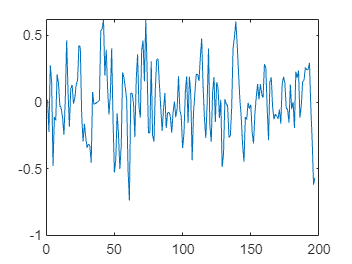

close all
clear
clc
%data = readmatrix('sub-03_sherlock__Mov_dmn-tmseries.xlsx');
load("F:\conn_projectDMN2\results\preprocessing\ROI_Subject003_Condition001.mat");
plot(data{1,7})

test = cell2mat(data);


%T considered as number of data points analyzed, f as number of brain
%regions
f = test();
f = f';
f = f([34:42, 44], :)

f =    -0.1469    0.1374    0.2936   -0.1143   -0.1189   -0.2217   -0.0849    0.0744   -0.0141   -0.3622   -0.2114   -0.0581   -0.4288   -0.0495    0.7083    0.2521    0.1103   -0.0311    0.2579    0.1014   -0.3429   -0.0389    0.5941    0.3479   -0.1777    0.0822   -0.0336    0.3639   -0.0008   -0.2079   -0.5754   -0.3784    0.0983   -0.1071   -0.1110   -0.1032   -0.0944   -0.0847   -0.0742   -0.1041    0.7862    0.7113    0.4420    0.0675    0.1996    0.1602   -0.0243    0.0155   -0.0382   -0.3721
   -0.1566    0.2341    0.1101    0.1598   -0.2733   -0.0421   -0.3963    0.1198   -0.0788   -0.4707   -0.0076    0.2321   -0.3822    0.1713    0.1507    0.1618    0.0790   -0.1560    0.2413   -0.1377   -0.2192   -0.0484    0.4095    0.1417    0.4706    0.2584    0.2435    0.0919   -0.1418   -0.4240   -0.2519    0.1174   -0.1401    0.3918   -0.1364   -0.1286   -0.1196   -0.1097   -0.0989    0.3940    0.1898    0.6766   -0.3156   -0.0117    0.0326    0.0462    0.0524   -0.0044   -0.2161   -0


T =197; t = (1:T)/T; Const=0;
Z = gsp_distanz(f').^2;
% we can multiply the pairwise distances with a number to control sparsity
[W] = gsp_learn_graph_log_degrees(Z, 1, 5);

# iters: 1000. Rel primal: 1.2304e-03 Rel dual: 3.5380e-04  OBJ 3.718e+01
Time needed is 0.036271 seconds


% clean up zeros
W(W<1e-5) = 0;
G = gsp_graph(W);

%running MVMD
norm_input=f/max(max(f));
[u, u_hat, omega] = MVMD_ver1(norm_input, 2000, 0, 10, 0, 1, 1e-7);

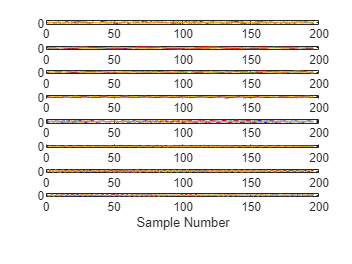

%Testing between 2 nodes 
c1 = 1;
c2 = 2;
c3 = 3;
c4 = 4;
c5 = 5;
c6 = 6;
c7 = 7;
c8 = 8;
c9 = 9;
c10 = 10; 
figure;
subplot(911); plot(T*t(:,1:T-1), f(c1, 1:T-1), "blue", T*t(:,1:T-1), f(c2, 1:T-1), 'red', T*t(:,1:T-1), f(c3, 1:T-1),T*t(:,1:T-1), f(c4, 1:T-1),T*t(:,1:T-1), f(c5, 1:T-1),T*t(:,1:T-1), f(c6, 1:T-1),T*t(:,1:T-1), f(c7, 1:T-1),T*t(:,1:T-1), f(c8, 1:T-1),T*t(:,1:T-1), f(c9, 1:T-1),T*t(:,1:T-1), f(c10, 1:T-1))
subplot(912); plot(T*t(:,1:T-1), u(1, 1:T-1, c1), "blue", T*t(:,1:T-1), u(1, 1:T-1, c2), 'red',T*t(:,1:T-1), u(1, 1:T-1, c3),T*t(:,1:T-1), u(1, 1:T-1, c4),T*t(:,1:T-1), u(1, 1:T-1, c5),T*t(:,1:T-1), u(1, 1:T-1, c6),T*t(:,1:T-1), u(1, 1:T-1, c7),T*t(:,1:T-1), u(1, 1:T-1, c8),T*t(:,1:T-1), u(1, 1:T-1, c9),T*t(:,1:T-1), u(1, 1:T-1, c10))
subplot(913); plot(T*t(:,1:T-1), u(2, 1:T-1, c1), "blue", T*t(:,1:T-1), u(2, 1:T-1, c2), 'red',T*t(:,1:T-1), u(2, 1:T-1, c3),T*t(:,1:T-1), u(2, 1:T-1, c4),T*t(:,1:T-1), u(2, 1:T-1, c5),T*t(:,1:T-1), u(2, 1:T-1, c6),T*t(:,1:T-1), u(2, 1:T-1, c7),T*t(:,1:T-1), u(2, 1:T-1, c8),T*t(:,1:T-1), u(2, 1:T-1, c9),T*t(:,1:T-1), u(2, 1:T-1, c10))
subplot(914); plot(T*t(:,1:T-1), u(3, 1:T-1, c1), "blue", T*t(:,1:T-1), u(3, 1:T-1, c2), 'red',T*t(:,1:T-1), u(3, 1:T-1, c3),T*t(:,1:T-1), u(3, 1:T-1, c4),T*t(:,1:T-1), u(3, 1:T-1, c5),T*t(:,1:T-1), u(3, 1:T-1, c6),T*t(:,1:T-1), u(3, 1:T-1, c7),T*t(:,1:T-1), u(3, 1:T-1, c8),T*t(:,1:T-1), u(3, 1:T-1, c9),T*t(:,1:T-1), u(3, 1:T-1, c10))
subplot(915); plot(T*t(:,1:T-1), u(4, 1:T-1, c1), "blue", T*t(:,1:T-1), u(4, 1:T-1, c2), 'red',T*t(:,1:T-1), u(4, 1:T-1, c3),T*t(:,1:T-1), u(4, 1:T-1, c4),T*t(:,1:T-1), u(4, 1:T-1, c5),T*t(:,1:T-1), u(4, 1:T-1, c6),T*t(:,1:T-1), u(4, 1:T-1, c7),T*t(:,1:T-1), u(4, 1:T-1, c8),T*t(:,1:T-1), u(4, 1:T-1, c9),T*t(:,1:T-1), u(4, 1:T-1, c10))
subplot(916); plot(T*t(:,1:T-1), u(5, 1:T-1, c1), "blue", T*t(:,1:T-1), u(5, 1:T-1, c2), 'red',T*t(:,1:T-1), u(5, 1:T-1, c3),T*t(:,1:T-1), u(5, 1:T-1, c4),T*t(:,1:T-1), u(5, 1:T-1, c5),T*t(:,1:T-1), u(5, 1:T-1, c6),T*t(:,1:T-1), u(5, 1:T-1, c7),T*t(:,1:T-1), u(5, 1:T-1, c8),T*t(:,1:T-1), u(5, 1:T-1, c9),T*t(:,1:T-1), u(5, 1:T-1, c10))
subplot(917); plot(T*t(:,1:T-1), u(6, 1:T-1, c1), "blue", T*t(:,1:T-1), u(6, 1:T-1, c2), 'red',T*t(:,1:T-1), u(6, 1:T-1, c3),T*t(:,1:T-1), u(6, 1:T-1, c4),T*t(:,1:T-1), u(6, 1:T-1, c5),T*t(:,1:T-1), u(6, 1:T-1, c6),T*t(:,1:T-1), u(6, 1:T-1, c7),T*t(:,1:T-1), u(6, 1:T-1, c8),T*t(:,1:T-1), u(6, 1:T-1, c9),T*t(:,1:T-1), u(6, 1:T-1, c10))
subplot(918); plot(T*t(:,1:T-1), u(7, 1:T-1, c1), "blue", T*t(:,1:T-1), u(7, 1:T-1, c2), 'red',T*t(:,1:T-1), u(7, 1:T-1, c3),T*t(:,1:T-1), u(7, 1:T-1, c4),T*t(:,1:T-1), u(7, 1:T-1, c5),T*t(:,1:T-1), u(7, 1:T-1, c6),T*t(:,1:T-1), u(7, 1:T-1, c7),T*t(:,1:T-1), u(7, 1:T-1, c8),T*t(:,1:T-1), u(7, 1:T-1, c9),T*t(:,1:T-1), u(7, 1:T-1, c10)),xlabel('Sample Number')

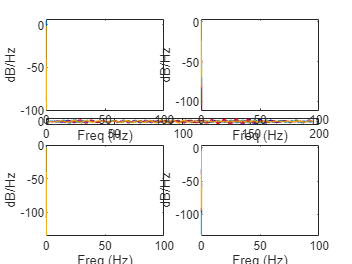

%Plotting of freqz
SampleRate = 0.67;
P = 4;
for X = 1:P
    [pxx,f] = pwelch(pagetranspose(u(X+1,:,:)),197,0,1024,SampleRate);
    subplot(2,2,X); box on; plot(f,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 100])
end

similarity_matrix = ConnectivityMatrixTest(u)

similarity_matrix = similarity_matrix(:,:,1) =

    1.0000    0.9710    0.5533    0.7555   -0.3004   -0.0058   -0.6814   -0.1710    0.6393   -0.8150
    1.0000    0.7377    0.7446    0.7553   -0.7681   -0.1535   -0.6295    0.6797    0.8034    0.3103
    1.0000    0.8400    0.7268    0.7981   -0.6126   -0.4498   -0.4135   -0.3148   -0.4097   -0.5308
    1.0000    0.8897    0.7072    0.8274   -0.4613   -0.5482   -0.0501   -0.5592    0.3502   -0.4188
    1.0000    0.4467    0.5541    0.3857   -0.1637    0.0361   -0.3325    0.1847    0.6449   -0.3192
    1.0000    0.5168    0.6177    0.4023   -0.3048   -0.2006   -0.3051    0.1996    0.1637    0.0567
    1.0000    0.5660    0.3128    0.4136   -0.1387   -0.1986    0.3298    0.0989    0.4781    0.1415
    1.0000    0.2239    0.3563    0.4328    0.1254    0.0445    0.1611    0.3111    0.1838    0.3007
    1.0000    0.1195    0.0093    0.3058   -0.1447   -0.2050   -0.0807    0.4208    0.7913    0.4377
    1.0000   -0.1799   -0.3136   -0.0592   

% figure

similarity_matrix(similarity_matrix<0.001)=0;
figure('Position',[489, 343, 714, 420])
nLabels = {'MPFC',	'LP (L)',	'LP (R)',	'PCC',	'SML (L)', 'SML(R)', 'SMS',	'VM',	'VO',	'S ACC'}

nLabels = 1×10 cell array
    {'MPFC'}    {'LP (L)'}    {'LP (R)'}    {'PCC'}    {'SML (L)'}    {'SML(R)'}    {'SMS'}    {'VM'}    {'VO'}    {'S ACC'}


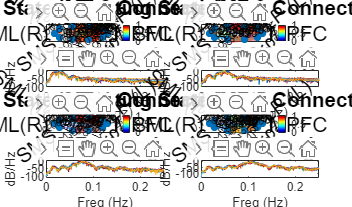

%nLabels = {'Anterior cingulate and medial prefrontal cortex','Hippocampal formation','Inferior parietal cortex','Lateral Temporal cortex','Posterior cingulate cortex'};
%nLabels = {'1','2','3','4','5','6','7','8','9','10'};
g=graph(squeeze(similarity_matrix(2,:,:)));
g = rmedge(g, 1:numnodes(g), 1:numnodes(g));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(4,2,1); s1=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s1.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Resting State IMF 2 Connectivity','FontSize',14)

g=graph(squeeze(similarity_matrix(3,:,:)));
g = rmedge(g, 1:numnodes(g), 1:numnodes(g));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(4,2,2); s2=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s2.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Resting State IMF 3 Connectivity','FontSize',14)


[pxx,freq] = pwelch(pagetranspose(u(2,:,:)),197,0,1024,SampleRate);
subplot(4,2,3); s3=plot(freq,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 0.25]);
title('IMF 2 band','FontSize',14)


[pxx,freq] = pwelch(pagetranspose(u(3,:,:)),197,0,1024,SampleRate);
subplot(4,2,4);s4=plot(freq,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 0.25]);
title('IMF 3 band','FontSize',14)

g=graph(squeeze(similarity_matrix(4,:,:)));
g = rmedge(g, 1:numnodes(g), 1:numnodes(g));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(4,2,5); s1=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s1.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Resting State IMF 4 Connectivity','FontSize',14)

g=graph(squeeze(similarity_matrix(5,:,:)));
g = rmedge(g, 1:numnodes(g), 1:numnodes(g));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(4,2,6); s2=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s2.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Resting State IMF 5 Connectivity','FontSize',14)


[pxx,freq] = pwelch(pagetranspose(u(4,:,:)),197,0,1024,SampleRate);
subplot(4,2,7); s3=plot(freq,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 0.25]);
title('IMF 4 band','FontSize',14)


[pxx,freq] = pwelch(pagetranspose(u(5,:,:)),197,0,1024,SampleRate);
subplot(4,2,8);s4=plot(freq,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 0.25]);
title('IMF 5 band','FontSize',14)